Helper Functions

function face = vec2pts(vec)
    face = reshape(vec, [72, 2]);
end

function k = preserve_var(eigvals, thresh) 
    eigsum = sum(eigvals);
    csum = 0;
    for i = 1:numel(eigvals)
        csum = csum + eigvals(i);
        tv = csum / eigsum;
        if tv > thresh
            k = i;
            break
        end
    end
end

First Step: Extract images

clear; close all; clc;

if ~isfolder("hand_points")
    unzip hand_points.zip
end

% Load all data (do not edit!)
X = zeros(17, 144);

for i = 1:17
    fname = strcat('hand_points/Hand/hand.', num2str(i), '.pts');
    h = table2array(readtable(fname, "FileType", "text"));
    X(i, :) = [h(:,1); h(:,2)]';
end

Visualisation

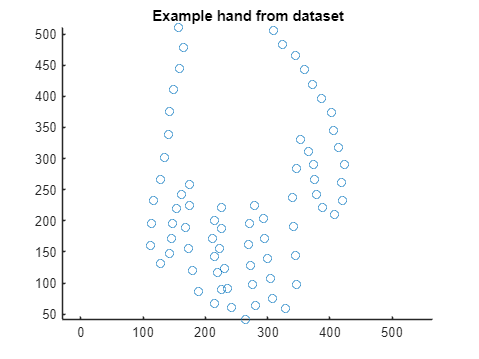

j = 3; % try some different values
hand = vec2pts(X(j,:));
figure, scatter(hand(:,1), hand(:,2))
title("Example hand from dataset");
axis equal

Task 2: Mean centering

X_mean = sum(X)/length(X)

X_mean =    35.3056   37.1250   39.3819   41.0903   42.6528   44.4097   46.2917   47.0625   48.3819   49.9444   50.1042   50.7639   50.0903   47.4722   45.8611   44.8264   44.1597   42.9097   40.9444   39.6667   39.2708   40.0000   40.8264   41.3889   39.6250   36.9653   36.3819   35.8542   34.8333   34.2847   32.5556   31.8611   32.1944   32.4792   32.7847   32.9167   30.8194   28.2778   28.0417   27.6319   26.5972   26.6528   25.9236   24.4375   23.7917   23.6319   23.7292   23.6250   21.7292   19.2014



hand_mean = vec2pts(X_mean)

hand_mean =    35.3056   59.6667
   37.1250   57.3125
   39.3819   55.3542
   41.0903   52.9097
   42.6528   50.3958
   44.4097   47.9375
   46.2917   45.6042
   47.0625   42.3681
   48.3819   39.3403
   49.9444   36.4097


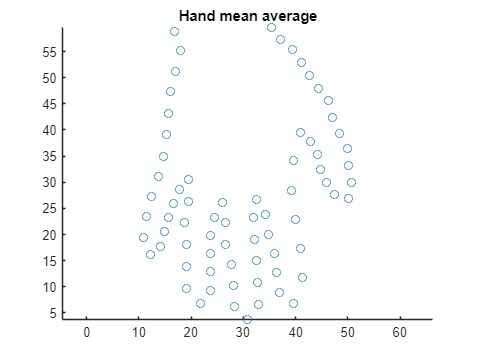

figure, scatter(hand_mean(:,1), hand_mean(:,2))
title("Hand mean average");
axis equal


X_centered = X - X_mean

X_centered =   248.6944  261.8750  281.6181  293.9097  305.3472  318.5903  332.7083  336.9375  343.6181  354.0556  354.8958  360.2361  353.9097  334.5278  323.1389  315.1736  311.8403  306.0903  294.0556  290.3333  286.7292  291.0000  295.1736  298.6111  285.3750  266.0347  261.6181  258.1458  251.1667  247.7153  237.4444  234.1389  237.8056  242.5208  247.2153  251.0833  238.1806  217.7222  211.9583  206.3681  195.4028  195.3472  191.0764  184.5625  185.2083  189.3681  195.2708  200.3750  190.2708  167.7986
  257.6944  272.8750  288.6181  298.9097  309.3472  320.5903  332.7083  333.9375  339.6181  348.0556  349.8958  355.2361  351.9097  330.5278  318.1389  310.1736  306.8403  301.0903  290.0556  286.3333  282.7292  287.0000  291.1736  293.6111  280.3750  260.0347  256.6181  254.1458  247.1667  244.7153  235.4444  229.1389  231.8056  233.5208  237.2153  238.0833  220.1806  202.7222  200.9583  197.3681  189.4028  190.3472  185.0764  177.5625  176.2083  178.3681  183.2708  185.3750  173.

Task 3: PCA

C = cov(X_centered)

C = 1.0e+03 *

    0.5828    0.5647    0.5723    0.5552    0.5370    0.5277    0.5122    0.4678    0.4229    0.3831    0.3654    0.3444    0.3434    0.3511    0.3652    0.3787    0.4071    0.4465    0.4906    0.4525    0.3815    0.2950    0.2143    0.1265    0.0371    0.0797    0.1461    0.2166    0.2604    0.3287    0.4030    0.3691    0.3295    0.2838    0.2393    0.1902    0.1592    0.1844    0.2275    0.2778    0.3257    0.3668    0.4098    0.4354    0.4427    0.4371    0.4381    0.4373    0.4247    0.4355
    0.5647    0.5520    0.5585    0.5380    0.5177    0.5068    0.4889    0.4418    0.3946    0.3525    0.3307    0.3055    0.3038    0.3125    0.3292    0.3459    0.3771    0.4208    0.4696    0.4427    0.3783    0.2990    0.2227    0.1397    0.0553    0.0959    0.1583    0.2253    0.2662    0.3301    0.4006    0.3666    0.3289    0.2845    0.2415    0.1931    0.1625    0.1867    0.2300    0.2787    0.3249    0.3643    0.4065    0.4348    0.4448    0.4417    0.4454    0.4473    

[eigvecs, D] = eig(C)

eigvecs =    -0.0220    0.0334   -0.0965   -0.0015    0.1233   -0.2462    0.2620    0.0536   -0.2814   -0.2766   -0.0931   -0.0372    0.0412   -0.1277   -0.0521    0.0257   -0.0941    0.0301    0.0111   -0.1961    0.0854    0.0135   -0.0311    0.1407    0.0026   -0.0387   -0.0330   -0.0630    0.1125   -0.0461    0.1827   -0.0416    0.0676   -0.0749    0.0596   -0.0593    0.0332    0.0253    0.0237    0.0058    0.0207   -0.0074    0.0060   -0.0056   -0.0253    0.0057   -0.0395    0.0123    0.1176   -0.0283
    0.0299   -0.0361    0.1253   -0.0476    0.0127    0.0491   -0.1823   -0.0385   -0.0224   -0.1266   -0.0067   -0.1396    0.0459    0.0249    0.0014    0.0234    0.0212    0.1355   -0.1580   -0.0818   -0.0552   -0.0245   -0.0571   -0.0551    0.0330    0.1375    0.2435    0.0838   -0.1071    0.0007   -0.0218   -0.0211    0.0950    0.0557    0.0348    0.1302   -0.0675   -0.0418    0.0928   -0.0461    0.0766    0.0155    0.0287   -0.0339   -0.0705    0.1007    0.0138    0.0413   -0.048

D = 1.0e+04 *

   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0   -0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

eigvals = diag(D)

eigvals = 1.0e+04 *

   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


eigvals = flip(eigvals)

eigvals = 1.0e+04 *

    2.6424
    0.8475
    0.5658
    0.4244
    0.2635
    0.1386
    0.0433
    0.0229
    0.0135
    0.0060


eigvals = fliplr(eigvals)

eigvals = 1.0e+04 *

    2.6424
    0.8475
    0.5658
    0.4244
    0.2635
    0.1386
    0.0433
    0.0229
    0.0135
    0.0060


Task 4: Reconstructing hands

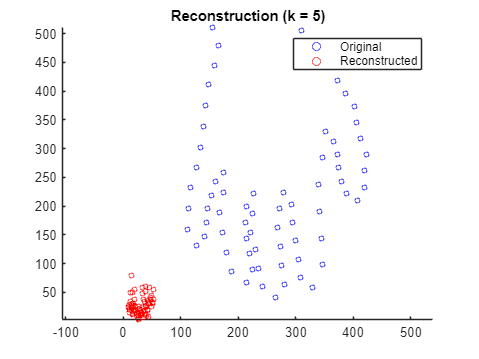

k = 3;
example = X(k, :);
pts = vec2pts(example);
figure; scatter(pts(:, 1), pts(:,2), 14, "b");
axis equal;
hold on;

% How many eigenvectors do we need to reconstruct hands well?
b = eigvecs.' * (example - X_mean)';
k = preserve_var(eigvals, 0.90);
b(k:end) = 0;

recon = X_mean' + eigvecs * b;
pts = vec2pts(recon');
scatter(pts(:,1), pts(:,2), 14, "r");
hold off;
legend("Original", "Reconstructed");
title(strcat("Reconstruction (k = ", num2str(k), ")"));